N = 1000

N = 1000

numbers = rand(1, N)

numbers =     0.7748    0.3300    0.3158    0.7246    0.5850    0.7778    0.3596    0.1847    0.5737    0.4831    0.4216    0.3173    0.9726    0.2582    0.5671    0.3521    0.3120    0.0094    0.6681    0.8857    0.4213    0.8586    0.9480    0.3761    0.2033    0.1792    0.3063    0.8503    0.5256    0.8284    0.1069    0.6171    0.5668    0.2609    0.0023    0.2873    0.8213    0.8951    0.9958    0.0084    0.7328    0.0846    0.6333    0.8051    0.8300    0.5672    0.2600    0.7845    0.1692    0.2743


numbers2 = rand_eca(1, N)

numbers2 =     0.1367    0.7109    0.9453    0.9414    0.0195    0.4609    0.8711    0.6641    0.6875    0.1797    0.1016    0.4375    0.6992    0.9844    0.0703    0.8477    0.2969    0.2344    0.5625    0.7617    0.4961    0.0586    0.1680    0.7188    0.9336         0    0.1875    0.3438    0.4766    0.1719    0.7461    0.0430    0.7773    0.6602    0.0898    0.9102    0.0977    0.5312    0.3125    0.0469    0.0273    0.7500    0.5586    0.8711    0.2930    0.3086    0.7539    0.1211    0.7812    0.8594



num_bins = 16;
bin_edges = (0:num_bins) ./ num_bins

bin_edges =          0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000



function bin_loc = find_bin(bin_edges, number)
    for i = 1:(length(bin_edges)-1)
        % number fit within [bin_edge, bin_edge)
        if ( number >= bin_edges(i) ) && ( number < bin_edges(i+1) ) 
            bin_loc = i;
            break;
        end
    end
end

function counts = count_bins(bin_edges, data)
    counts = zeros(1, length(bin_edges) - 1);
    for i=1:length(data)
        bin_loc = find_bin(bin_edges, data(i));
        counts(bin_loc) = counts(bin_loc) + 1;
    end
end

counts = count_bins(bin_edges, numbers)

counts =     70    52    53    75    60    73    62    61    56    64    69    61    69    74    56    45


counts2 = count_bins(bin_edges, numbers2)

counts2 =     63    53    70    68    53    70    54    68    81    56    61    52    73    57    71    50


Then I want to see how the observed compares to the actual

What is an actual? For each bin, there would be equal likely hood of finding.

function error = normalize_for_chi_sqaured(counts, N)
    num_bins = length(counts);
    uniform_per_bin_count = N / num_bins;
    true_uniform = zeros(1, num_bins) + uniform_per_bin_count; 
    error = sum( (counts - true_uniform).^2 ./ true_uniform );
end
normalize_for_chi_sqaured(counts, N)

ans = 18.3040

then we can plot what the best would have looked like

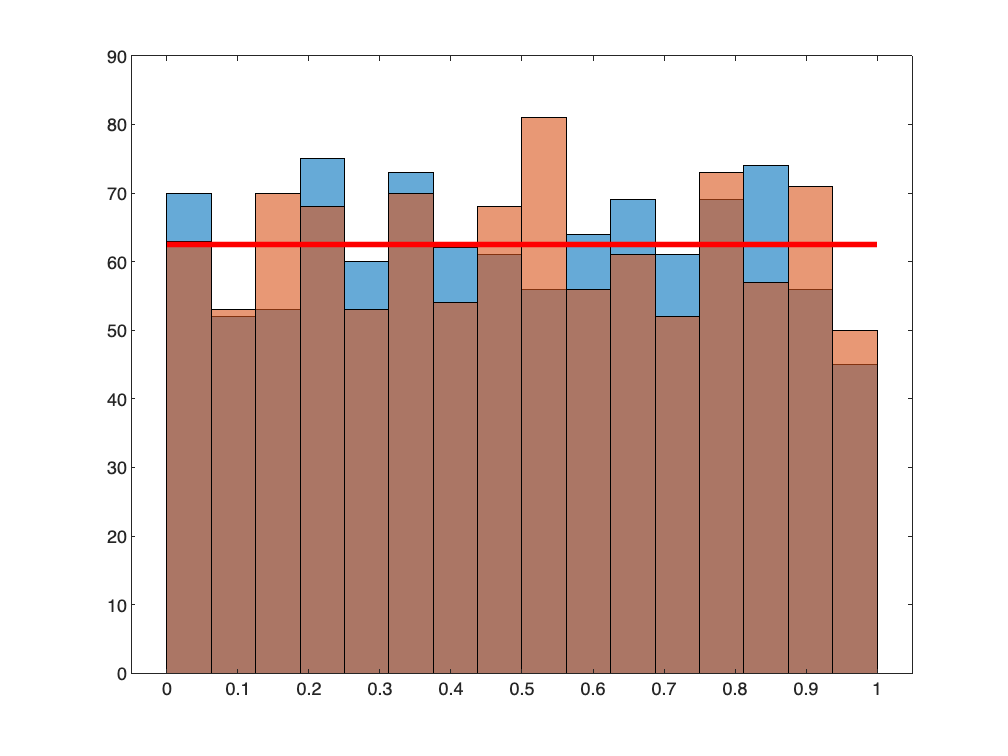

histogram(numbers, bin_edges)
hold on
histogram(numbers2, bin_edges)
hold on
plot([0 1], zeros(1, 2) + N / num_bins, "r-", "LineWidth", 3)
hold off

h_0 is that rand() is a uniform distrbution for n bins

b_1 unequal fruencies and not random uniform

alpha of 0.05 means that we reject h_0 5% of the time, when we should have failed to reject it.

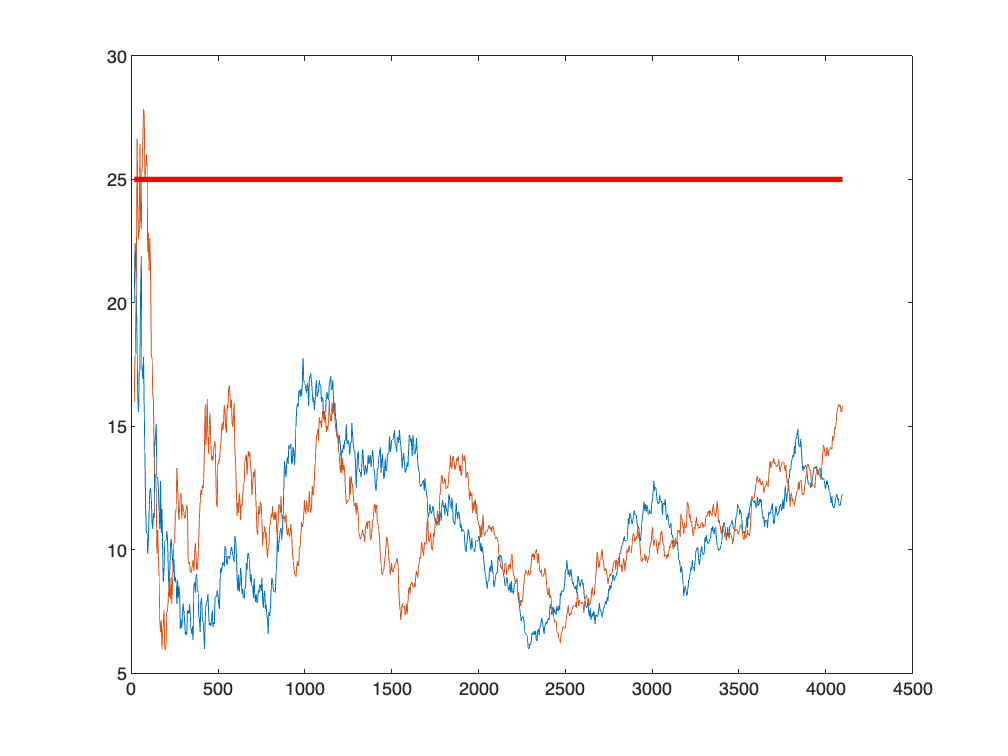

CRV = 24.996; % Critiical value for alpha=0.95 for df=15
num_bins = 16;
bin_edges = (0:num_bins) ./ num_bins;
max_val = 2^12;
Ns = ceil(linspace(16, max_val, 1000));
rng(0);
rng_eca();
rand1 = rand(1, max_val);
rand2 = rand_eca(1, max_val);
outputs = zeros(1, length(Ns));
outputs2 = zeros(1, length(Ns));
for i=1:length(Ns)
    N_i = Ns(i);
    numbers_i = rand1(1:N_i);
    numbers2_i = rand2(1:N_i);

    counts_i = count_bins(bin_edges, numbers_i);
    counts2_i = count_bins(bin_edges, numbers2_i);

    outputs(i) = normalize_for_chi_sqaured(counts_i, N_i);
    outputs2(i) = normalize_for_chi_sqaured(counts2_i, N_i);
end
plot(Ns, outputs)
hold on
plot(Ns, outputs2)
hold on
plot([Ns(1) Ns(end)], zeros(1, 2) + CRV, "r-", "LineWidth", 3)
hold off